clc
clear all
%simulation step times
Tsim = 1e-5;
%electrical motor parameters
Rs = 0.8;
Ld = 1.6e-3;
Lq = 3.2e-3;
L = diag([Ld,Lq]);
inv_L = L^-1;
J = [0 -1;1 0;];
we = 3000*5/60*2*pi;
Psi_dm = 0.047;


%position observation error caused by parameters mismatch within the
%model-based sensorless drive
Tilde_theta = pi/6;

%Init electrical motor operation states
Id0 = -4;
Iq0 = 4;
Ud0 = Id0 * Rs - we * Lq * Iq0;
Uq0 = Iq0 * Rs + we * Ld * Id0 + we * Psi_dm;

%Setting the additional small signal injection for multiparameter
%estimation
Umd = 8.0;
Umq = 8.0;
Fh = 400;

%Pre-set covariance matrices of reconstructed states, parameters and
%measurement
Qx = eye(2) * 0.01;
Qp = diag([Rs*0.01,1/Ld,1/Ld/10,1/Lq,Psi_dm*0.01]) * 1;
R = eye(2) * 7.5;

%Run the multiparameter estimation with different initial values from -50%
%to 50%.
InitParam_Mat = zeros(5,5);
ParamConstant = [Rs,Ld,0,Lq,Psi_dm];
for i = 1:5
    InitParam_Mat(i,:) = ParamConstant + ParamConstant * (i - 3)/2 * 0.5;
end
for i = 1:5
    InitParam = InitParam_Mat(i,:)';
    InitParam(2) = 1/InitParam(2);
    InitParam(4) = 1/InitParam(4);
    sim_data(i) = sim("DEKFSensorless.slx");
end

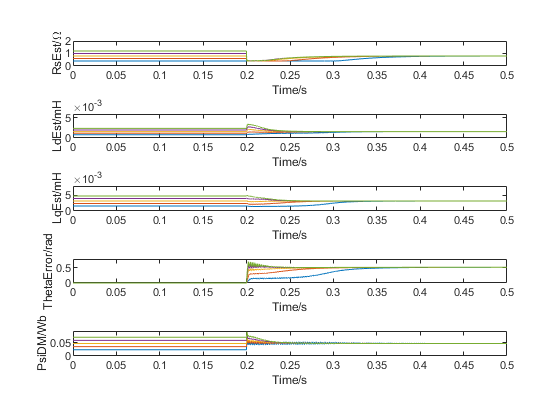

%Output the simulation data.
figure()
subplot(5,1,1)
plot(sim_data(1).RsEst{1}.Values.Time,sim_data(1).RsEst{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).RsEst{1}.Values.Time,sim_data(i).RsEst{1}.Values.Data);
end
hold off
xlim([0 0.5])
ylim([0 2])
xlabel("Time/s")
ylabel("RsEst/{\Omega}")
% figure()
subplot(5,1,2)
plot(sim_data(1).LdEst{1}.Values.Time,sim_data(1).LdEst{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).LdEst{1}.Values.Time,sim_data(i).LdEst{1}.Values.Data);
end
hold off
xlim([0 0.5])
ylim([0 6e-3])
xlabel("Time/s")
ylabel("LdEst/mH")
% figure()
subplot(5,1,3)
plot(sim_data(1).LqEst{1}.Values.Time,sim_data(1).LqEst{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).LqEst{1}.Values.Time,sim_data(i).LqEst{1}.Values.Data);
end
hold off
xlim([0 0.5])
ylim([0 8e-3])
xlabel("Time/s")
ylabel("LqEst/mH")
% figure()
subplot(5,1,4)
plot(sim_data(1).TildeTheta{1}.Values.Time,sim_data(1).TildeTheta{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).TildeTheta{1}.Values.Time,sim_data(i).TildeTheta{1}.Values.Data);
end
hold off
xlim([0 0.5])
ylim([0 0.8])
xlabel("Time/s")
ylabel("ThetaError/rad")
% figure()
subplot(5,1,5)
plot(sim_data(1).Psi_dm{1}.Values.Time,sim_data(1).Psi_dm{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).Psi_dm{1}.Values.Time,sim_data(i).Psi_dm{1}.Values.Data);
end
hold off
xlim([0 0.5])
ylim([0 Psi_dm*2])
xlabel("Time/s")
ylabel("PsiDM/Wb")

InitParam = [Rs,Ld,0,Lq,Psi_dm]' * 1.5;
InitParam(2) = 1/InitParam(2);
InitParam(4) = 1/InitParam(4);
for i = 1:4
    Qp = diag([Rs*0.01,1/Ld,1/Ld/10,1/Lq,Psi_dm*0.01]) .*5^(i-4);
    sim_data(i) = sim("DEKFSensorless.slx");
end

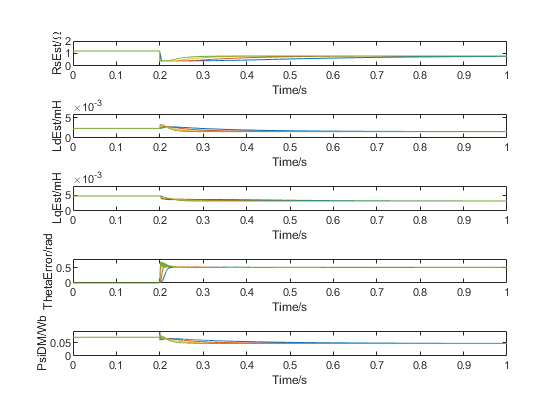

%Output the simulation data.
figure()
subplot(5,1,1)
plot(sim_data(1).RsEst{1}.Values.Time,sim_data(1).RsEst{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).RsEst{1}.Values.Time,sim_data(i).RsEst{1}.Values.Data);
end
hold off
xlim([0 1])
ylim([0 2])
xlabel("Time/s")
ylabel("RsEst/{\Omega}")
% figure()
subplot(5,1,2)
plot(sim_data(1).LdEst{1}.Values.Time,sim_data(1).LdEst{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).LdEst{1}.Values.Time,sim_data(i).LdEst{1}.Values.Data);
end
hold off
xlim([0 1])
ylim([0 6e-3])
xlabel("Time/s")
ylabel("LdEst/mH")
% figure()
subplot(5,1,3)
plot(sim_data(1).LqEst{1}.Values.Time,sim_data(1).LqEst{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).LqEst{1}.Values.Time,sim_data(i).LqEst{1}.Values.Data);
end
hold off
xlim([0 1])
ylim([0 8e-3])
xlabel("Time/s")
ylabel("LqEst/mH")
% figure()
subplot(5,1,4)
plot(sim_data(1).TildeTheta{1}.Values.Time,sim_data(1).TildeTheta{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).TildeTheta{1}.Values.Time,sim_data(i).TildeTheta{1}.Values.Data);
end
hold off
xlim([0 1])
ylim([0 0.8])
xlabel("Time/s")
ylabel("ThetaError/rad")
% figure()
subplot(5,1,5)
plot(sim_data(1).Psi_dm{1}.Values.Time,sim_data(1).Psi_dm{1}.Values.Data);
hold on
for i = 2:5
    plot(sim_data(i).Psi_dm{1}.Values.Time,sim_data(i).Psi_dm{1}.Values.Data);
end
hold off
xlim([0 1])
ylim([0 Psi_dm*2])
xlabel("Time/s")
ylabel("PsiDM/Wb")